# Train Short Time Fourier Transform

Live script used to train the Short time fourier transform network

tic
fs = 100;
fol = "D:\3minSept22";
ds_all=ResampleDatastore(fol,fs,'DataAugmentation',false);
ds_test = ResampleDatastore(fol,fs,'TestSet',false);
ds90_all=ResampleDatastore(fol,fs,'DataAugmentation',true);
ds90_test = ResampleDatastore(fol,fs,'TestSet',true);
toc

Used Matched Age and Gender subjects/sessions of HEA and STR

# HEA subjects/sessions: 595/629
# STR subjects/sessions: 527/585
# TBI subjects/sessions: 552/629


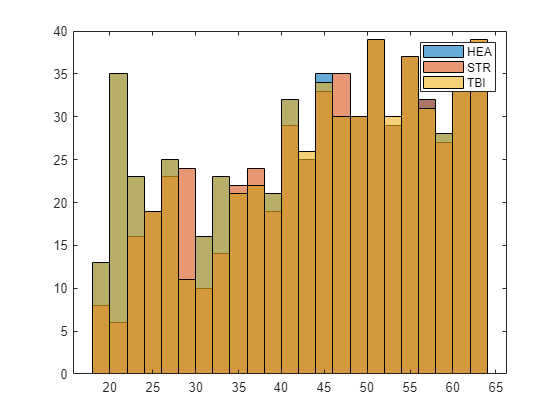

[HEA,STR,TBI] = MatchSubjects();

s = split(HEA.Location,'\');
s = string(s(:,9));
s = split(s,'.');
HEA = s(:,1);
s = split(STR.Location,'\');
s = string(s(:,9));
s = split(s,'.');
STR = s(:,1);
s = split(TBI.Location,'\');
s = string(s(:,9));
s = split(s,'.');
TBI = s(:,1);

Check for overlaps

f = string(ds_all.Datastore.Files);
in_HEA = [];
in_STR = [];
in_TBI = [];
for i = 1:length(f)
    for j = 1:length(HEA)
        if contains(f(i),HEA(j))
            in_HEA = [in_HEA i];
            break
        end
    end
    for j = 1:length(STR)
        if contains(f(i),STR(j))
            in_STR = [in_STR i];
            break
        end
    end
    for j = 1:length(TBI)
        if contains(f(i),TBI(j))
            in_TBI = [in_TBI i];
            break
        end
    end
end
%in_TBI = find(ds_all.Labels == "TBI")';
in = [in_HEA, in_STR, in_TBI];
ds_match = subset(ds_all,in);
ds_match_test = subset(ds_test,in);
ds90_match = subset(ds90_all,in);
ds90_match_test = subset(ds90_test,in);

Set aside >=50 patients for IV

c = string(categories(ds_match.Labels));
numsub = max(50,floor(min(countcats(ds_match.Labels))*.2));
disp("Using " + numsub + " for IV.")

Using 582 for IV.


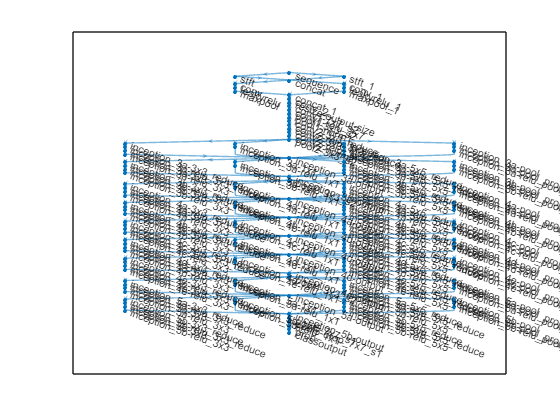

in_iv = [];
in_cv = [];
for i = 1:length(c)
    in = find(ds_match.Labels == c(i));
    r = randperm(length(in));
    in_iv = [in_iv; in(r(1:numsub))];
    in_cv = [in_cv; in(r(numsub+1:end))];
end
X_Train=subset(ds_match,in_cv);
X_Test=subset(ds_match_test,in_iv);
Y_Train=subset(ds90_match,in_cv);
Y_Test=subset(ds90_match_test,in_iv);
save("STFTData.mat","X_Train","X_Test","Y_Train","Y_Test")

Run Network

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:09 |       29.17% |       33.31% |      16.1284 |      15.9765 |      1.0000e-04 |
|       1 |          50 |       00:02:20 |       54.17% |              |       2.7504 |              |      1.0000e-04 |
|       1 |         100 |       00:04:21 |       50.00% |       45.67% |       1.1569 |       1.6274 |      1.0000e-04 |
|       1 |         150 |       00:05:35 |       41.67% |              |       1.7076 |              |      1.0000e-04 |
|       1 |         200 |       

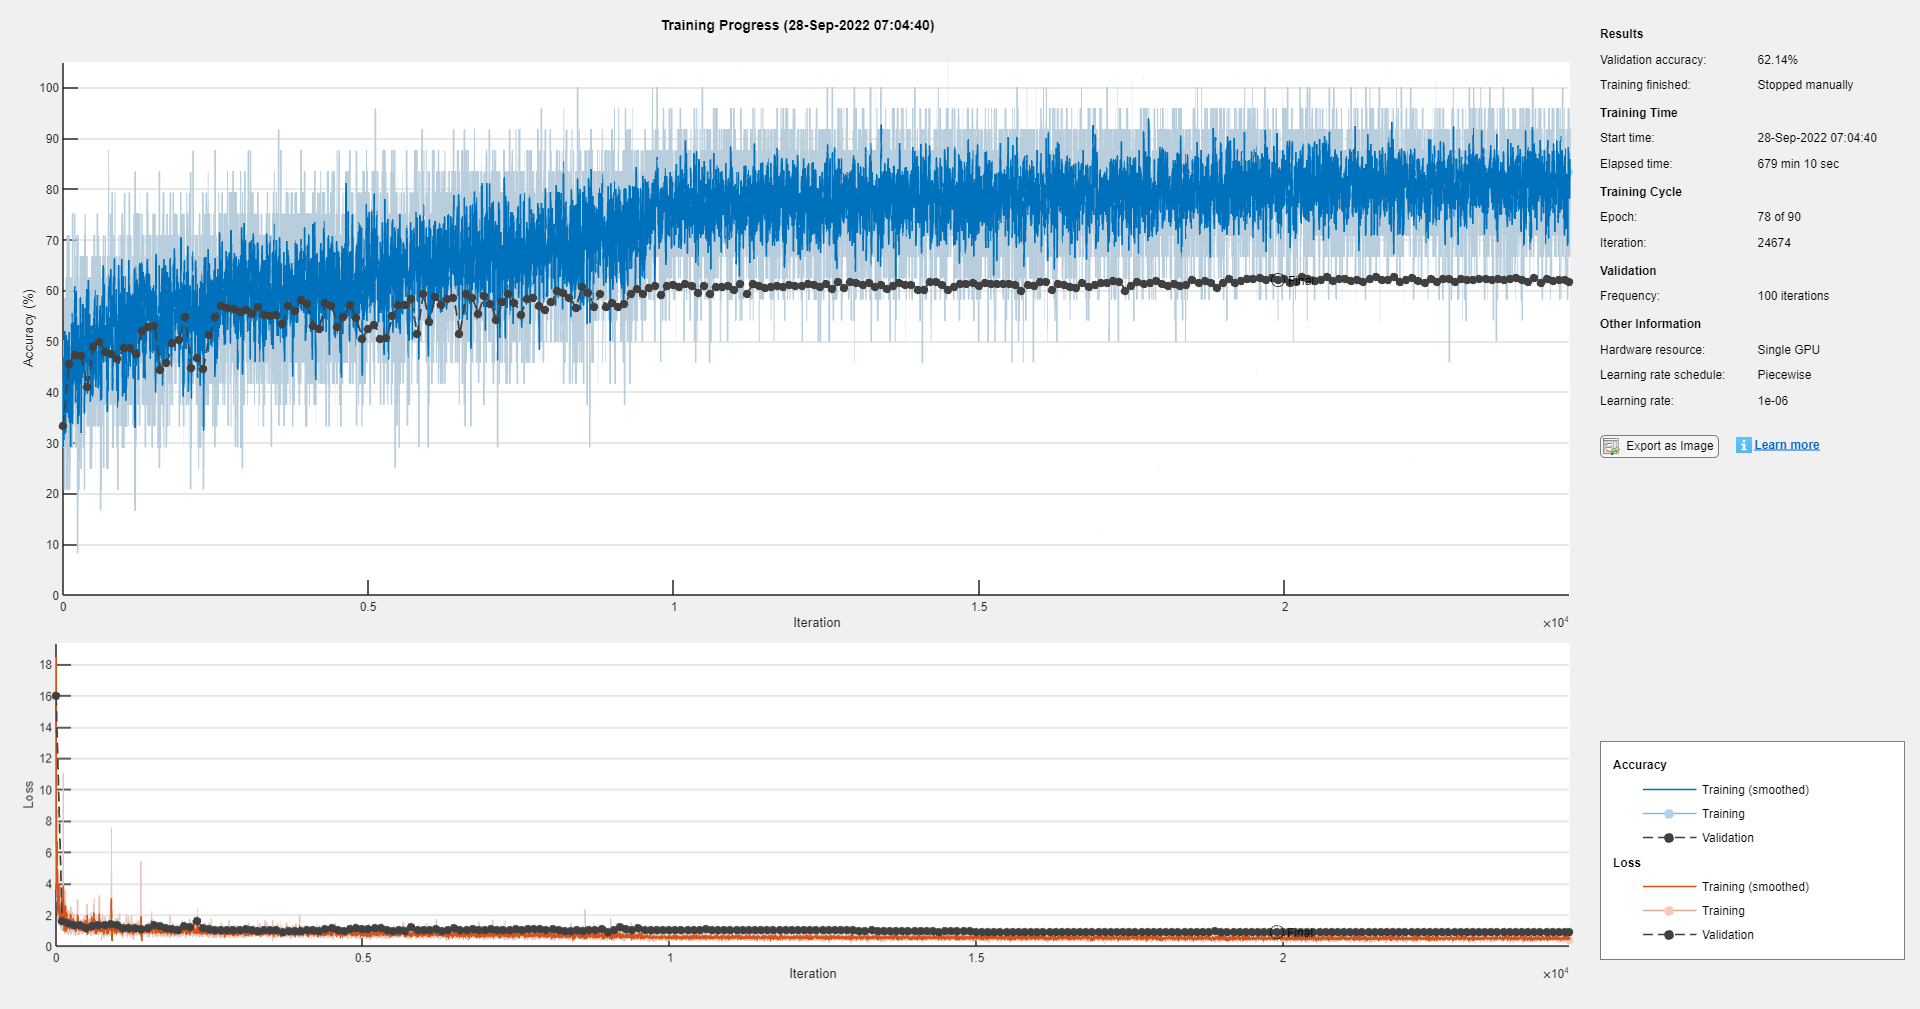

% gpuDevice(1);
% %load("STFTLayers.mat")
% reset(X_Train);
% reset(X_Test);
% miniBatchSize=24;
% X_Train.MiniBatchSize=miniBatchSize;
% X_Test.MiniBatchSize=miniBatchSize;
% opts=trainingOptions("adam","Plots","training-progress","ExecutionEnvironment","gpu", ...
%     "Shuffle","every-epoch","MiniBatchSize",miniBatchSize,"MaxEpochs",30*3,...
%     "InitialLearnRate",.0001,"LearnRateSchedule","piecewise","LearnRateDropPeriod",30,"GradientThreshold",10,...
%     "OutputNetwork","best-validation-loss","ValidationData",X_Test,"ValidationFrequency",100);
% net=trainNetwork(X_Train,lgraph_2,opts);

## CNN Models

### Layers:

3 types of convolution 

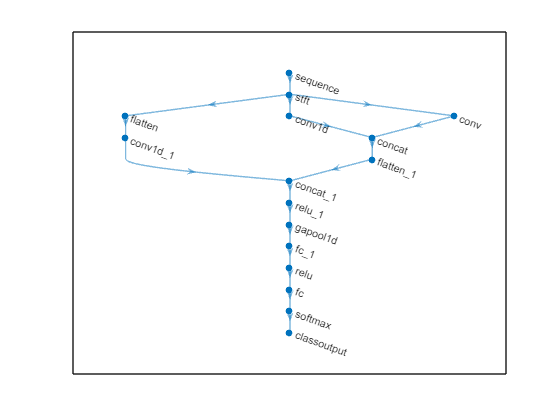

load("STFTNet.mat","lgraph_2");
plot(lgraph_2)

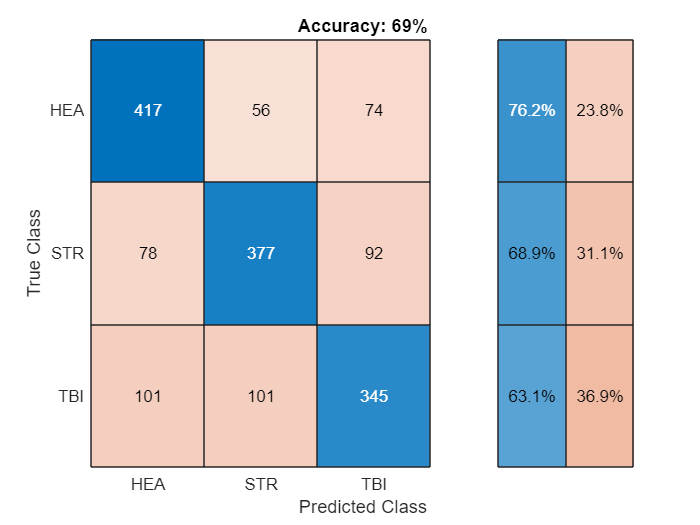

load("STFTNet.mat")
Snet4 = MdlResults(net4a,Y_Test,Y_Test.Labels);
classify(Snet4);

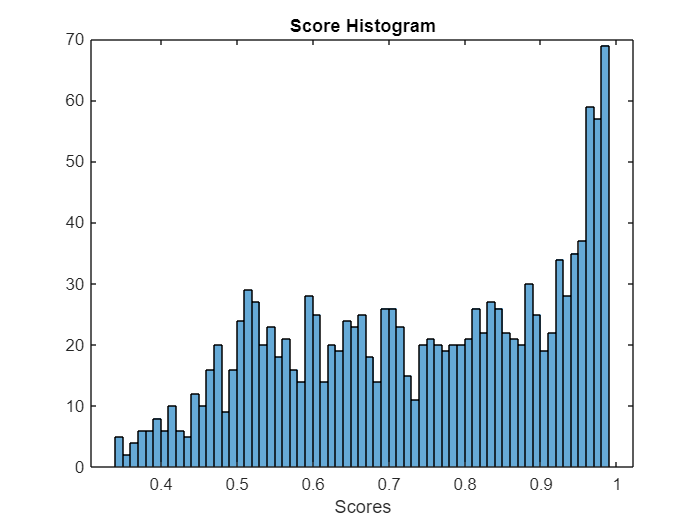

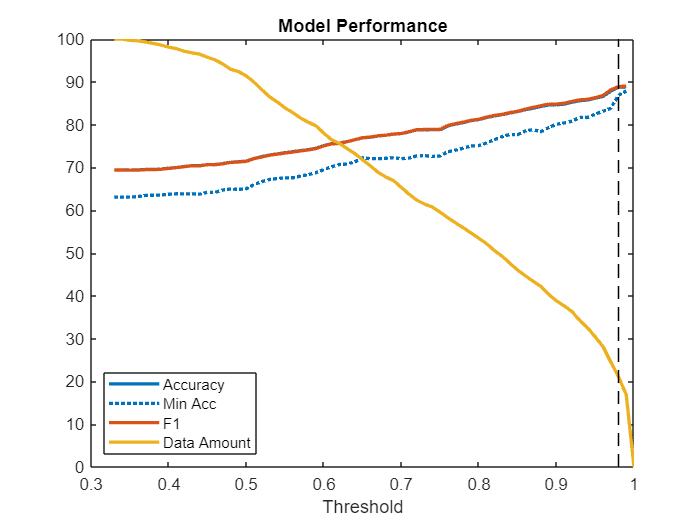

Data Remaining: 0.21085


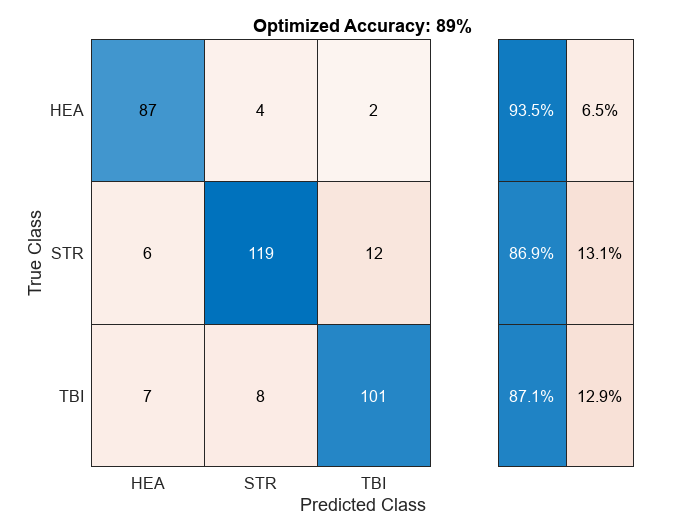

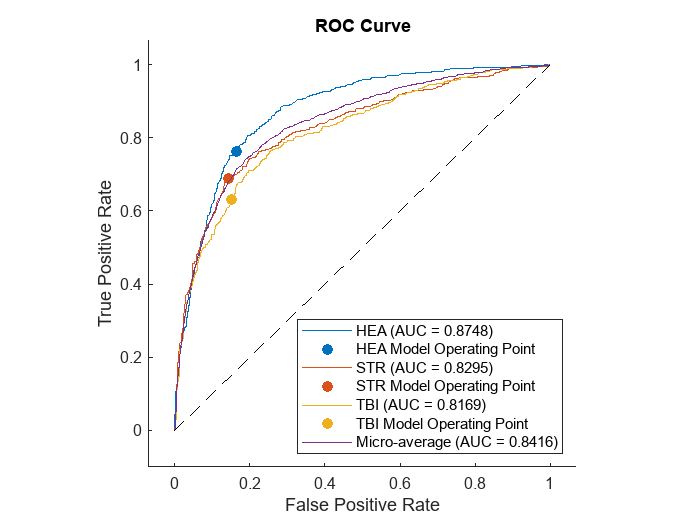

metrics(Snet4);

## Supporting Functions

function [CV,IV]=pathname(path,C)
if nargin<2
    C=["HEA","STR","TBI"];
end
d=load("CVIVsplit_LSTM.mat");
j=1;
j2=1;
for k=1:length(C)
    x=d.(C(k)+"_TCV");
    y=d.(C(k)+"_TIV");
    %CV=cell(1,height(x));
    %IV=cell(1,height(y));
    for i=1:height(x)
        if length(C)>1
            CV{j}=fullfile(path,C(k), ...
                [eightdigit(x.Subject(i)),'_',x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        else
            CV{j}=fullfile(path,C(k),eightdigit(x.Subject(i)), ...
                [x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        end
        j=j+1;
    end
    for i=1:height(y)
        if length(C)>1
            IV{j}=fullfile(path,C(k), ...
                [eightdigit(x.Subject(i)),'_',x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        else
            IV{j}=fullfile(path,C(k),eightdigit(x.Subject(i)), ...
                [x.Session(i),'_',num2str(x.Date.Year(i)),'_', ...
                doubledigit(x.Date.Month(i)),'_',doubledigit(x.Date.Day(i)), ...
                '-',num2str(x.Min(i)),'.mat']);
        end
        j2=j2+1;
    end
end
    function y=doubledigit(x)
        y=num2str(x);
        if length(y)<2
            y=['0',y];
        end
    end
    function y=eightdigit(x)
        y=num2str(x);
        if length(y)<8
            y=[repelem('0',8-length(y)),y];
        end
    end
end
function in=MatchSubject(Files,CV)
sFiles=SubSplit(Files);
sCV=unique(SubSplit(CV));
in=ismember(sFiles,sCV);
    function s=SubSplit(x)
        if size(x,1)==1
            x=x';
        end
        s=split(x,'\');
        s=s(:,end);
        s=split(s,'_');
        s=s(:,1);
    end
end

function [y,labels] = TemporalSplit(ds,fs)
reset(ds);
ds.MiniBatchSize = 1;
y = cell(ds.NumObservations*5,1);
for i = 1:ds.NumObservations
    T = read(ds);
    x = cell2mat(T.predictors);
    t = 1 + 5*(i-1);
    labels(t:t+4) = T.responses;
    y{t} = x(:,1:90*fs);
    y{t+1} = x(:,(90*fs+1):end);
    for j = 2:4
        r = randi(90*fs-2)+1;
        y{t+j} = x(:,r:r+(90*fs-1));
    end
end
end

function layers = freezeWeights(layers,excludeLayers)
% layers = freezeWeights(layers) sets the learning rates of all the
% parameters of the layers in the layer array |layers| to zero if they already have weights.
if nargin <2
    excludeLayers = [];
end
layernums = 1:1:size(layers,1);
layernums(excludeLayers) = [];
for ii = layernums
    props = properties(layers(ii));
    for p = 1:numel(props)
        propName = props{p};
        if ~isempty(regexp(propName, 'LearnRateFactor$', 'once'))
            if ~isempty(layers(ii).Weights)
                layers(ii).(propName) = 0;
            end
        end
    end
end

end

function lgraph = createLgraphUsingConnections(layers,connections)

lgraph = layerGraph();
for i = 1:numel(layers)
    lgraph = addLayers(lgraph,layers(i));
end

for c = 1:size(connections,1)
    lgraph = connectLayers(lgraph,connections.Source{c},connections.Destination{c});
end

end